%% Setup
clear; clc;
%rng(0,'twister'); % reproducibility

%% Read data (last column = target)s
dataa = readtable("[EXT2]BEEF-vdW-1836rows-2nd-16Features-MamunHighT2019.csv", "VariableNamingRule","preserve");
%dataa = readtable("[MAIN5]2ndML-Features-comp_df_filtered_by_min_H_sp_energy.csv", "VariableNamingRule","preserve");
datau = table2array(dataa);

%% Parameters
acak       = 300;     % outer repeats (reshuffle, fixed test split) change this for resampling
repetition = 1;     % inner repeats (reshuffle train/val per g) keep this 1
kf         = 5;     % K-folds
RMF        = 65;     % model selector (see switch below)
XFlag      = 4;     % feature set selector

% Prealloc across outer loops
TestRMSEBest = zeros(acak,1);
TestRMSEMean = zeros(acak,1);
StdTestRMSE  = zeros(acak,1);

TestMAEBest  = zeros(acak,1);
TestMAEMean  = zeros(acak,1);
StdTestMAE   = zeros(acak,1);

RsqMeanComb  = zeros(acak,1);
StdRsq       = zeros(acak,1);

KeepRMSEMean = zeros(acak,1);
KeepRMSEstd  = zeros(acak,1);
KeepMAEMean  = zeros(acak,1);
KeepMAEstd   = zeros(acak,1);
KeepRsqMean  = zeros(acak,1);
KeepRsqstd   = zeros(acak,1);

% For plotting at the end (we'll retain the last run's vectors)
plot_Y_true_cv  = [];
plot_Y_pred_cv  = [];
plot_Y_true_tst = [];
plot_Y_pred_tst = [];

for g = 1:acak
    fprintf('Outer repetition g = %d\n', g);

    % Shuffle once and split: first 100 rows as fixed test set
    rows = size(datau,1);
    P = randperm(rows);
    datax    = datau(P,:);
    datakeep = datax(1:275,:);   % fixed test set
    data     = datax(276:end,:); % train/val pool

    % Containers across inner repeats
    CV_RMSE_s   = zeros(repetition,1);
    CV_MAE_s    = zeros(repetition,1);
    Rsq_s       = zeros(repetition,1);
    KeepRMSE_s  = zeros(repetition,1);
    KeepMAE_s   = zeros(repetition,1);
    KeepRsq_s   = zeros(repetition,1);

    % (optional) per-fold validation metrics if you want later analysis
    ValRMSE_mat = zeros(repetition, kf);
    ValMAE_mat  = zeros(repetition, kf);

    for s = 1:repetition
        %fprintf('  Inner repetition s = %d\n', s);

        % Reshuffle train/val pool for this repeat
        rows2 = size(data,1);
        P2    = randperm(rows2);
        dataS = data(P2,:);

        % Basic sizes
        NL = size(dataS,1);
        NF = size(dataS,2)-1;  % number of features

        % Feature set (safeguarded)
        %1.n_s, 3.n_d,5.mean Z,9.r_atom,10.OS_max 
        switch XFlag
            case 1
                pv = 1:min(NF,16);
            case 2
                pv = 1:min(NF,4);
            case 3
                pv = 1:min(NF,3);
            case 4
                pv = intersect([1 3 5 9 10], 1:NF);
                if isempty(pv), pv = 1:min(NF,3); end
            case 5
                pv = 1;
            otherwise
                pv = 1:min(NF,16);
        end

        % KFold partition on indices (data already shuffled)
        cv = cvpartition(NL,'KFold',kf);

        % Hold CV predictions (for all items exactly once)
        Yv  = zeros(NL,1);  % predicted (CV)
        Yvt = zeros(NL,1);  % true (CV)

        % For fixed test set: store per-fold predictions for later averaging
        datakeepX     = datakeep(:,pv);
        YKeepFit_all  = zeros(size(datakeep,1), kf);

        % Per-fold metrics (optional bookkeeping)
        TrainRMSE = zeros(kf,1);
        TrainMAE  = zeros(kf,1);
        ValRMSE   = zeros(kf,1);
        ValMAE    = zeros(kf,1);

        for k = 1:kf
            InTrain = training(cv,k);
            InTest  = test(cv,k);

            DTrain = dataS(InTrain,:);
            DTest  = dataS(InTest,:);

            XTrain = DTrain(:,pv);  YTrain = DTrain(:,end);
            XTest  = DTest(:,pv);   YTest  = DTest(:,end);

            % === Model selection ===
            switch RMF
                case 10
                    MdlFinal = fitlm(XTrain, YTrain, 'linear'); 
                case 11
                    MdlFinal = fitlm(XTrain, YTrain, 'interactions');
                case 12
                    MdlFinal = fitlm(XTrain, YTrain, 'purequadratic');
                case 13
                    MdlFinal = fitlm(XTrain, YTrain, 'linear', 'RobustOpts','on');
                case 14
                    MdlFinal = stepwiselm(XTrain, YTrain, ...
                        'Lower','constant','Upper','interactions','Verbose',0);
                % ---- Decision Trees ----
                case 20
                    MdlFinal = fitrtree(XTrain, YTrain, 'MinLeafSize',4);
                case 21
                    MdlFinal = fitrtree(XTrain, YTrain, 'MinLeafSize',12);
                case 22
                    MdlFinal = fitrtree(XTrain, YTrain, 'MinLeafSize',36);


% ---- SVM Regression ----
                case 30
                    MdlFinal = fitrsvm(XTrain, YTrain, 'KernelFunction','linear', ...
                        'Standardize',true);
                case 31
                    MdlFinal = fitrsvm(XTrain, YTrain, 'KernelFunction','gaussian', ...
                        'Standardize',true, 'KernelScale','auto');
                case 32
                    MdlFinal = fitrsvm(XTrain, YTrain, 'KernelFunction','polynomial', ...
                        'PolynomialOrder',2, 'Standardize',true);
                case 33
                    MdlFinal = fitrsvm(XTrain, YTrain, 'KernelFunction','polynomial', ...
                        'PolynomialOrder',3, 'Standardize',true);
      % ---- Ensembles ----
                case 50
                    MdlFinal = fitrensemble(XTrain, YTrain, ...
                        'Method','LSBoost','NumLearningCycles',200, ...
                        'LearnRate',0.1);
                case 51
                    MdlFinal = fitrensemble(XTrain, YTrain, ...
                        'Method','Bag','NumLearningCycles',200);                case 1  % GLM linear
                    MdlFinal = fitglm(XTrain, YTrain, 'linear');
                % ---- Gaussian Process Regression ----
                case 60
                    MdlFinal = fitrgp(XTrain, YTrain, ...
                        'Standardize',true, 'KernelFunction','squaredexponential', ...
                        'BasisFunction','constant');
                case 61
                    MdlFinal = fitrgp(XTrain, YTrain, ...
                        'Standardize',true, 'KernelFunction','matern32', ...
                        'BasisFunction','constant');
                case 62
                    MdlFinal = fitrgp(XTrain, YTrain, ...
                        'Standardize',true, 'KernelFunction','matern52', ...
                        'BasisFunction','constant');
                case 63
                    MdlFinal = fitrgp(XTrain, YTrain, ...
                        'Standardize',true, 'KernelFunction','rationalquadratic', ...
                        'BasisFunction','constant');
                case 64
                    MdlFinal = fitrgp(XTrain, YTrain, ...
                        'Standardize',true, 'KernelFunction','exponential', ...
                        'BasisFunction','constant');
                % THE BEST model below (GPR ard squared exponential)
                case 65
                    MdlFinal = fitrgp(XTrain, YTrain, ...
                        'Standardize',true, 'KernelFunction','ardsquaredexponential', ...
                        'BasisFunction','constant');
                % ---- kNN ----
                case 600
                    MdlFinal = fitrknn(XTrain, YTrain, ...
                        'NumNeighbors',1, 'Standardize',true);
                case 610
                    MdlFinal = fitrknn(XTrain, YTrain, ...
                        'NumNeighbors',10, 'Standardize',true);
                case 620
                    MdlFinal = fitrknn(XTrain, YTrain, ...
                        'NumNeighbors',100, 'Standardize',true);
                case 630
                    MdlFinal = fitrknn(XTrain, YTrain, ...
                        'NumNeighbors',10, 'Standardize',true, ...
                        'Distance','cosine');

                % ---- Kernel Regression ----
                case 70
                    MdlFinal = fitrkernel(XTrain, YTrain, ...
                        'OptimizeHyperparameters','auto', ...
                        'HyperparameterOptimizationOptions',hyperopts);

                % ---- Neural Network ----
                case 81
                    MdlFinal = fitrnet(XTrain, YTrain, ...
                        'LayerSizes',10, 'Standardize',true);
                case 82
                    MdlFinal = fitrnet(XTrain, YTrain, ...
                        'LayerSizes',50, 'Standardize',true);
                case 83
                    MdlFinal = fitrnet(XTrain, YTrain, ...
                        'LayerSizes',100, 'Standardize',true);

                % ---- Generalized Additive Model ----
                case 90
                    MdlFinal = fitrgam(XTrain, YTrain, ...
                        'Interactions','all');  % enable pairwise interactions

                % ---- Optional legacy bagger ----
                case 95
                    % TreeBagger (regression). Note: predict returns Nx1 double.
                    MdlFinal = TreeBagger(200, XTrain, YTrain, ...
                        'Method','regression','OOBPrediction','off');

                otherwise
                    error('Unsupported RMF=%d', RMF);
            end

            % === Predictions & metrics ===
            YTrainFit = predict(MdlFinal, XTrain);
            YTestFit  = predict(MdlFinal, XTest);

            TrainRMSE(k) = sqrt(mean((YTrainFit - YTrain).^2));
            TrainMAE(k)  = mean(abs(YTrainFit - YTrain));
            ValRMSE(k)   = sqrt(mean((YTestFit  - YTest ).^2));
            ValMAE(k)    = mean(abs(YTestFit  - YTest ));

            % Collect CV predictions
            Yv(InTest)  = YTestFit;
            Yvt(InTest) = YTest;

            % Fixed test set prediction for this fold
            YKeepFit_all(:,k) = predict(MdlFinal, datakeepX);
        end

        % === Aggregate CV ===
        CV_RMSE = sqrt(mean((Yv - Yvt).^2));
        CV_MAE  = mean(abs(Yv - Yvt));
        Rsq     = 1 - sum((Yvt - Yv).^2) / sum((Yvt - mean(Yvt)).^2);

        CV_RMSE_s(s) = CV_RMSE;
        CV_MAE_s(s)  = CV_MAE;
        Rsq_s(s)     = Rsq;

        ValRMSE_mat(s,:) = ValRMSE.';
        ValMAE_mat(s,:)  = ValMAE.';

        % === Aggregate fixed test set over folds (average predictions) ===
        YKeepFit_mean = mean(YKeepFit_all, 2);
        y_true_test   = datakeep(:,end);

        KeepRMSE_s(s) = sqrt(mean((YKeepFit_mean - y_true_test).^2));
        KeepMAE_s(s)  = mean(abs(YKeepFit_mean - y_true_test));
        KeepRsq_s(s)  = 1 - sum((y_true_test - YKeepFit_mean).^2) / ...
                           sum((y_true_test - mean(y_true_test)).^2);

        % Save last loop's vectors for plotting after all loops
        if g==acak && s==repetition
            plot_Y_true_cv  = Yvt;
            plot_Y_pred_cv  = Yv;
            plot_Y_true_tst = y_true_test;
            plot_Y_pred_tst = YKeepFit_mean;
        end
    end

    % === Across inner repeats (per g) ===
    TestRMSEBest(g) = min(CV_RMSE_s);
    TestRMSEMean(g) = mean(CV_RMSE_s);
    StdTestRMSE(g)  = std(CV_RMSE_s);

    TestMAEBest(g)  = min(CV_MAE_s);
    TestMAEMean(g)  = mean(CV_MAE_s);
    StdTestMAE(g)   = std(CV_MAE_s);

    RsqMeanComb(g)  = mean(Rsq_s);
    StdRsq(g)       = std(Rsq_s);

    KeepRMSEMean(g) = mean(KeepRMSE_s);
    KeepRMSEstd(g)  = std(KeepRMSE_s);
    KeepMAEMean(g)  = mean(KeepMAE_s);
    KeepMAEstd(g)   = std(KeepMAE_s);
    KeepRsqMean(g)  = mean(KeepRsq_s);
    KeepRsqstd(g)   = std(KeepRsq_s);
end

Outer repetition g = 1



%% Validation metrics combined across outer loops
TestRMSEBest2  = min(TestRMSEMean)

TestRMSEBest2 = 0.2780

TestRMSEMean2  = mean(TestRMSEMean)

TestRMSEMean2 = 0.2780

StdTestRMSE2   = std(TestRMSEMean)

StdTestRMSE2 = 0

TestMAEBest2   = min(TestMAEMean)

TestMAEBest2 = 0.1640

TestMAEMean2   = mean(TestMAEMean)

TestMAEMean2 = 0.1640

StdTestMAE2    = std(TestMAEMean)

StdTestMAE2 = 0

RsqMeanComb2   = mean(RsqMeanComb)

RsqMeanComb2 = 0.7474

StdRsq2        = std(RsqMeanComb)

StdRsq2 = 0


%% Fixed test metrics combined across outer loops
KeepRMSEMean2  = mean(KeepRMSEMean)

KeepRMSEMean2 = 0.2618

KeepRMSEstd2   = std(KeepRMSEMean)

KeepRMSEstd2 = 0

KeepMAEMean2   = mean(KeepMAEMean)

KeepMAEMean2 = 0.1691

KeepMAEstd2    = std(KeepMAEMean)

KeepMAEstd2 = 0

KeepRsqMean2   = mean(KeepRsqMean)

KeepRsqMean2 = 0.7648

KeepRsqstd2    = std(KeepRsqMean)

KeepRsqstd2 = 0

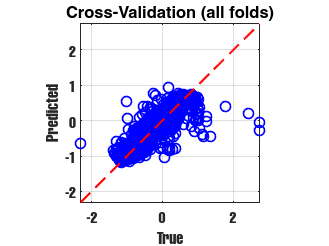


%% Plots (x = true, y = predicted)
% Style: hollow blue circles, red dashed y=x

% Cross-validation scatter
figure('Name','CV (k-fold)');
scatter(plot_Y_true_cv, plot_Y_pred_cv, 36, ...
    'Marker','o','MarkerFaceColor','none','MarkerEdgeColor','b','LineWidth',1);
hold on;
minVal = min([plot_Y_true_cv; plot_Y_pred_cv]);
maxVal = max([plot_Y_true_cv; plot_Y_pred_cv]);
plot([minVal maxVal], [minVal maxVal], 'r--','LineWidth',1.25);
axis equal; xlim([minVal maxVal]); ylim([minVal maxVal]);
grid on; box on;
xlabel('True'); ylabel('Predicted'); title('Cross-Validation (all folds)');

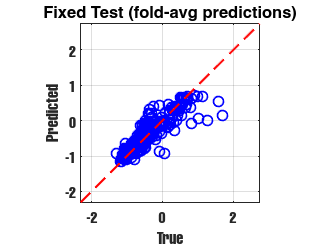


% Fixed test scatter (averaged predictions over folds)
figure('Name','Held-out Test (first 100 rows)');
scatter(plot_Y_true_tst, plot_Y_pred_tst, 36, ...
    'Marker','o','MarkerFaceColor','none','MarkerEdgeColor','b','LineWidth',1);
hold on;
minVal = min([plot_Y_true_cv; plot_Y_pred_cv]);
maxVal = max([plot_Y_true_cv; plot_Y_pred_cv]);
plot([minVal maxVal], [minVal maxVal], 'r--','LineWidth',1.25);
axis equal; xlim([minVal maxVal]); ylim([minVal maxVal]);
grid on; box on;
xlabel('True'); ylabel('Predicted'); title('Fixed Test (fold-avg predictions)');